# Ejemplo uso función PlotConfusion 

Load the  iris data set.  Create the training and test data set

`X` is a numeric matrix that contains four petal measurements for 150 irises. 

`Y` is a cell array of character vectors that contains the corresponding iris species: setosa, versicolor, virginica

load fisheriris
X = meas;
Y = species;

%Number of classes: NC=2 or NC=3
NC=2; 
%NC=3;

switch NC
    case 2   % Two classes: C2 and C3
        Xtrain=[ X(51:80,:) ; X(101:130,:)];
        Xtest=[ X(81:100,:) ; X(131:150,:)];
        
        Ytrain=[Y(51:80) ; Y(101:130)];
        Ytest=[ Y(81:100) ; Y(131:150)];
    case 3    % Three Clases
        Xtrain=[X(1:30,:) ; X(51:80,:) ; X(101:130,:)];
        Xtest=[X(31:50,:) ; X(81:100,:) ; X(131:150,:)];
        
        Ytrain=[Y(1:30) ; Y(51:80) ; Y(101:130)];
        Ytest=[Y(31:50) ; Y(81:100) ; Y(131:150)];

    otherwise
        disp('other value')
end



Train a **naive Bayes classifier**. It is good practice to specify the class order.

Mdl = fitcnb(Xtrain,Ytrain,...
    'ClassNames',{'setosa','versicolor','virginica'});

Predict the labels of the training data.

YPredicted=predict(Mdl,Xtest);

Convert Y and Ypredicted in  an *N*-by-*M* matrix, where *N* is the number of classes and *M* is the number of observations. Each column of the matrix must be in one-of-N (one-hot) form, where a single element equal to 1 indicates the true label and all other elements equal 0.

switch NC
    case 2
        
        indc2=strcmp(Ytest,'versicolor')';
        indc3=strcmp(Ytest,'virginica')';
        Ycat=double([indc2; indc3]);
        
        indcp2=strcmp(YPredicted,'versicolor')';
        indcp3=strcmp(YPredicted,'virginica')';
        Ypred=double([indcp2; indcp3]);
    case 3 
        indc1=strcmp(Ytest,'setosa')'; 
        indc2=strcmp(Ytest,'versicolor')';
        indc3=strcmp(Ytest,'virginica')';
        Ycat=double([indc1; indc2; indc3]);
        
        indcp1=strcmp(YPredicted,'setosa')'; 
        indcp2=strcmp(YPredicted,'versicolor')';
        indcp3=strcmp(YPredicted,'virginica')';
        Ypred=double([indcp1; indcp2; indcp3]);
end          
        

Plot the confusion matrix. 

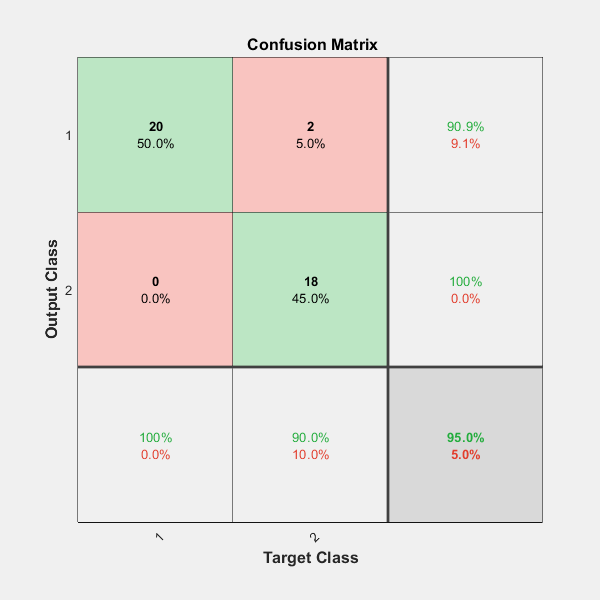

plotconfusion(Ycat,Ypred);